# 7주차 과제 — 보상기 설계

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 비례제어로 되는지 먼저 확인

- **2. 기본** (중간 · 40분 · 70점) — PD 로 그 문제 풀기

- **3. 도전** (선택 · 가산점 10점) — 제어입력 한계까지 넣고 설계

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

쓸 수 있는 도구 (강의노트 1-2 절)

- `rl_scan(C1, G, Kvec, true)` — 이득을 훑어 성능표를 만든다

- `ctrl_input(C, G)` — 계단 지령에 대한 제어입력

- `spec2pole(P_OS, ts)` — 사양을 $\zeta$, $\omega_n$ 으로

clc; close all;
s = tf('s');

## 1. 몸풀기 — 비례제어로 되는가

**강의노트 1-1 절과 1-3 절을 그대로 보면 됩니다.**

설계를 시작할 때 **가장 먼저 할 일**은 "제일 간단한 방법으로 되는지" 확인하는 것입니다. 되면 그걸로 끝이고, 안 되면 왜 안 되는지가 다음 수를 알려 줍니다.

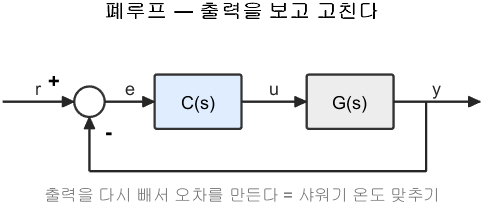

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

## 1-1. 문제


$$G(s) = \frac{1}{s(s+2)}$$


- 오버슈트 $\le 10\%$

- 정착시간 $\le 3$ 초

할 일 — 손으로 한 가지, 코드로 한 가지입니다.

**손으로** : 폐루프 특성방정식을 쓰고 **두 근의 합**이 무엇인지 확인하십시오.


$$s^2 + 2s + K = 0 \qquad \Rightarrow \qquad \text{두 근의 합} = \;?$$


복소근일 때 두 근은 $-\sigma \pm j\omega_d$ 이므로 합은 $-2\sigma$ 입니다. 그러면 $\sigma = \zeta\omega_n$ 이 $K$ 와 무관하게 얼마로 고정되는지 알 수 있습니다.

**코드로** : `TODO` 한 줄만 채우십시오.

G1 = 1/(s*(s+2));
[zmin, wmin] = spec2pole(10, 3);

fprintf('=== 1. 비례제어로 되는가 ===\n');
fprintf('  공식이 요구하는 것 : zeta >= %.4f , wn >= %.4f\n', zmin, wmin);
fprintf('  즉 zeta*wn >= %.4f 가 필요합니다\n', zmin*wmin);

T1 = rl_scan(1, G1, linspace(0.2, 20, 400));
ok1 = NaN;    % TODO : T1.stable & T1.OS <= 10 & T1.ts <= 3 으로 논리 벡터를 만드십시오

if islogical(ok1)
    if any(ok1)
        fprintf('  실측으로 만족하는 K = %.3f ~ %.3f  (훑은 400 점 중 %d 점)\n', ...
                min(T1.K(ok1)), max(T1.K(ok1)), sum(ok1));
    else
        fprintf('  실측으로도 만족하는 K 가 없습니다\n');
    end
end

## 1-2. 그림으로 보기

코드는 다 되어 있습니다.

figure;
tiledlayout(1,2,'TileSpacing','compact');
nexttile
rlocus(G1); hold on; sgrid(zmin, wmin);
xlim([-4 1]); ylim([-4 4]); grid on;
title('궤적(세로 직선)과 사양 영역');
nexttile
plot(T1.K, T1.ts, 'LineWidth', 2); hold on;
yline(3, 'r--', 'LineWidth', 1.5);
grid on; xlabel('이득 K'); ylabel('정착시간 [s]'); ylim([0 8]);
legend('실측 정착시간', '요구 3 s', 'Location', 'northeast');
title('이득을 아무리 바꿔도 정착시간이 안 줄어든다');

## 1-3. 답할 것 (두 문장이면 됩니다)

- $\zeta\omega_n$ 은 $K$ 와 무관하게 얼마로 고정되는가?

- 공식이 요구하는 값과 비교하면, 비례제어로 이 사양이 가능한가?

## 2. 기본 — PD 로 풀기

**강의노트 2절과 2-1 절을 그대로 보면 됩니다.**

PD 제어기는 개루프에 **영점 하나**를 더합니다.


$$C(s) = K\,(s + z)$$


영점은 궤적을 자기 쪽(왼쪽)으로 당깁니다. 그러면 1번에서 막혔던 "실수부를 못 바꾼다" 는 문제가 풀립니다.

이번에는 고를 것이 **둘**입니다. $z$ 와 $K$. 한꺼번에 풀 수 없으므로 $z$ 후보를 몇 개 잡고 표로 비교합니다.

## 2-1. 표 만들기

`TODO` 한 줄만 채우십시오.

주의 : `rl_scan` 의 첫 인자는 **이득을 뺀** 제어기입니다. PD 면 `(s+z)` 를 넣습니다. `K*(s+z)` 가 아닙니다.

z_list = [1 2 3 4 5];

fprintf('\n=== 2. PD 설계 ===\n');
fprintf('     z     만족 K 구간      고른 K   OS[%%]   ts[s]   max|u|\n');
fprintf('   -----  --------------  --------  ------  ------  -------\n');
for z = z_list
    C1 = 1;    % TODO : 이 줄을  C1 = (s + z);  로 바꾸십시오
    Tz = rl_scan(C1, G1, linspace(0.2, 20, 300), true);
    ok = Tz.stable & Tz.OS <= 10 & Tz.ts <= 3;
    if ~any(ok)
        fprintf('   %5.1f  만족하는 K 없음\n', z);
        continue
    end
    sub = Tz(ok,:);
    [~, j] = min(sub.umax);        % 제어입력이 가장 작은 것을 고른다
    fprintf('   %5.1f  %6.2f ~ %5.2f  %8.2f  %6.2f  %6.2f  %7.3f\n', ...
            z, min(sub.K), max(sub.K), sub.K(j), sub.OS(j), sub.ts(j), sub.umax(j));
end

## 2-2. 하나 골라 검증

위 표에서 하나를 고르십시오. `TODO` 두 줄을 채우면 그림이 나옵니다.

z_pick = NaN;    % TODO : 위 표에서 고른 영점
K_pick = NaN;    % TODO : 그때의 이득

if ~isnan(z_pick) && ~isnan(K_pick)
    C_pd = K_pick*(s + z_pick);
    Tcl  = feedback(C_pd*G1, 1);
    info = stepinfo(Tcl);
    t2   = (0:0.01:5)';
    [u2, ~, um2] = ctrl_input(C_pd, G1, t2);

    fprintf('\n  검증 : z = %.1f , K = %.2f\n', z_pick, K_pick);
    fprintf('    오버슈트 %.2f %%  (요구 10 이하)\n', info.Overshoot);
    fprintf('    정착시간 %.3f s   (요구 3 이하)\n', info.SettlingTime);
    fprintf('    최대 제어입력 %.3f\n', um2);

    figure;
    tiledlayout(1,3,'TileSpacing','compact');
    nexttile
    rlocus(G1*(s+z_pick)); hold on; sgrid(zmin, wmin);
    xlim([-8 1]); ylim([-6 6]); grid on;
    title(sprintf('PD 궤적 (z = %.1f)', z_pick));
    nexttile
    plot(t2, step(Tcl, t2), 'LineWidth', 2); hold on;
    yline(1,'k--'); yline(1.1,'r:'); xline(3,'r:');
    grid on; xlabel('시간 [s]'); ylabel('출력');
    legend('출력','목표','오버슈트 한계','정착시간 한계','Location','southeast');
    title('계단응답');
    nexttile
    plot(t2, u2, 'LineWidth', 2); grid on;
    xlabel('시간 [s]'); ylabel('제어입력 u');
    title('제어입력');
end

## 2-3. 손으로 확인할 것 하나

이 플랜트에서 PD 의 **초기 제어입력**에는 간단한 공식이 있습니다.

$t = 0^+$ 에서 $e(0) = 1$ 이고 $\dot{e}(0) = -K$ 이므로


$$u(0) = K\left(\dot{e}(0) + z\,e(0)\right) = K\,(z - K)$$


할 일 — 고른 $(z, K)$ 를 이 공식에 넣어 계산하고, 위 표의 `max|u|` 값과 같은지 확인하십시오. (한 줄이면 됩니다)

## 2-4. 답할 것 (두 문장이면 됩니다)

- $z$ 를 키우면 사양을 만족하는 데 **필요한 최소 이득**은 커지는가 작아지는가? 왜 그런지 한 줄로 설명하십시오 (힌트 : 영점이 궤적을 당긴다)

- 표에서 $z = 2$ 인 줄을 보십시오. 플랜트 극점이 $s = -2$ 인데 영점을 거기 놓았습니다. 오버슈트가 $0$ 인 이유가 무엇이겠는가?

## 3. 도전 (선택) — 제어입력 한계까지 넣고 설계

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

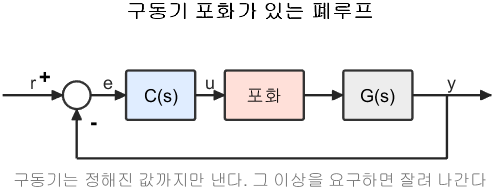

구동기 포화가 있는 폐루프

**그림 파일** `loop_saturation.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_saturation')`

플랜트를 바꿉니다. 이번에는 비례제어입니다.


$$G(s) = \frac{1}{s(s+2)(s+5)}, \qquad C(s) = K$$


사양

- 정착시간 $T_s < 5.2$ 초

- 오버슈트 $M_p < 1\%$

- $|u(t)| \le 5$

- 위를 만족하는 것 중 $\max|u|$ 가 **가장 작은** $K$ 를 고를 것

할 일

- `rl_scan(1, G, Kvec, true)` 로 표를 만들라

- 사양을 **하나씩 추가하며** $K$ 구간이 어떻게 좁아지는지 보여라

- 최종 $K^*$ 를 고르고 검증하라

답할 것 (두 문장)

- $K$ 구간의 아래쪽과 위쪽을 각각 막은 사양은 무엇인가?

- 비례제어에서 $\max|u|$ 가 왜 $K$ 와 같은가?

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 손 계산과 그림, 두 질문에 답했는가

- **2. 기본** 70점 — 표, 검증, 손 공식 확인, 두 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 제어입력을 확인하지 않은 경우

- $z$ 와 $K$ 를 고른 **이유**를 쓰지 않은 경우

- 코드가 오류로 멈추는 경우